# Analysis of Monte Carlo Results

Analysis the simulation results in more detail. In particular, consider any variation caused by the signal-to-noise ratio. 

## Load Monte Carlo simulation results

Load the data from the Monte Carlo simulation. 

% Find base directory
basedir = fileparts(pwd);

% Set data directory
datadir = fullfile(basedir,"data","DataExamplesv2");

% Set model director and file
modeldir = fullfile(basedir,"data","Models");
modelfilename = "ModelBaggedTreesDWPT5Lvl.mat";
% model variable name is mdlBag5lvl
waveletName = 'coif2';
waveletLevels = 5; 

% Set Monte Carlo directory and file
mcfolder = fullfile(basedir,"data","MonteCarlo");
mcfilename = "mcBagged5LvlResults.mat";

% Create pool of MATLAB workers
% tic; parpool('local',4); toc

% Load data
load(fullfile(mcfolder,mcfilename))

## Overall statistics

% Overall statistics
summary(tmcoutput)


Variables:

    BlockLength: 100000×1 double

        Values:

            Min         1.024e+05  
            Median      1.024e+05  
            Max         1.024e+05  

    SignalFile: 100000×1 string

    SignalStartIndx: 100000×1 double

        Values:

            Min                  11    
            Median       6.9362e+05    
            Max           8.028e+06    

    ContaminatedTrue: 100000×1 logical

        Values:

            True           49827       
            False          50173       

    FracBlockContaminated: 100000×1 double

        Values:

            Min                     0        
            Median                  0        
            Max               0.99995        

    ContaminationStartIndx: 100000×1 double

        Values:

            Min                    0          
            Median                 0          
            Max       

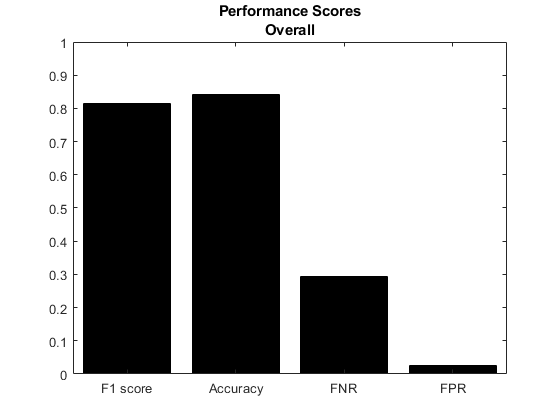

% Overall scores
[acc,fpr,fnr,f1] = scoreModel(tmcoutput.ContaminatedTrue,tmcoutput.ContaminatedPred);
scoresOA.acc = acc;
scoresOA.f1 = f1;
scoresOA.fpr = fpr;
scoresOA.fnr = fnr;
% Plot scores for comparison
c = categorical({'F1 score','Accuracy','FNR','FPR'},{'F1 score','Accuracy','FNR','FPR'});
bar(c,[f1; acc; fnr; fpr],'FaceColor','k');
ylim([0 1])
title({'Performance Scores';'Overall'})

## Contaminated files only

% Contaminated files only
tcontaminated = tmcoutput(tmcoutput.ContaminatedTrue == 1,:);
summary(tcontaminated)


Variables:

    BlockLength: 49827×1 double

        Values:

            Min         1.024e+05  
            Median      1.024e+05  
            Max         1.024e+05  

    SignalFile: 49827×1 string

    SignalStartIndx: 49827×1 double

        Values:

            Min                  11    
            Median       6.9069e+05    
            Max           8.028e+06    

    ContaminatedTrue: 49827×1 logical

        Values:

            True           49827       
            False              0       

    FracBlockContaminated: 49827×1 double

        Values:

            Min                  0.25        
            Median            0.62486        
            Max               0.99995        

    ContaminationStartIndx: 49827×1 double

        Values:

            Min                    1          
            Median             14298          
            Max             

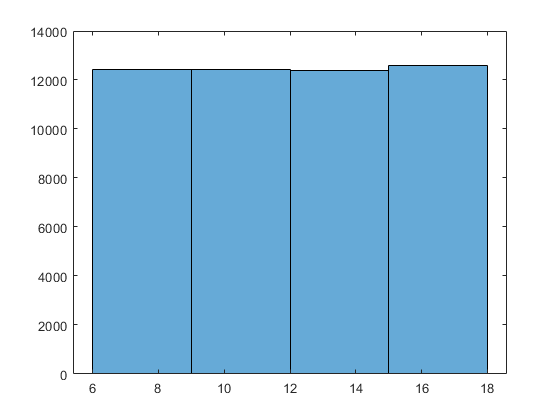

% Signal-to-noise ratio
edges = 6:3:18;
histogram(tcontaminated.SNRdB,edges)

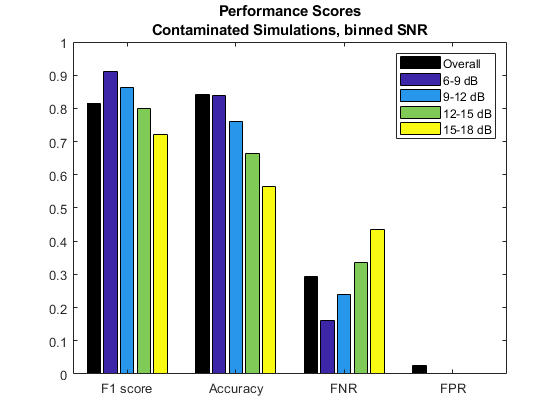

binsSNR = discretize(tcontaminated.SNRdB,edges);

[acc,fpr,fnr,f1] = splitapply(@scoreModel,tcontaminated.ContaminatedTrue,tcontaminated.ContaminatedPred,binsSNR);
% Plot scores for comparison
c = categorical({'F1 score','Accuracy','FNR','FPR'},{'F1 score','Accuracy','FNR','FPR'});
b = bar(c,[[scoresOA.f1 f1']; [scoresOA.acc acc']; [scoresOA.fnr fnr']; [scoresOA.fpr fpr']],'FaceColor','flat');
ylim([0 1])
legend({'Overall','6-9 dB','9-12 dB','12-15 dB','15-18 dB'})
title({'Performance Scores';'Contaminated Simulations, binned SNR'})
b(1).CData = [0 0 0];
for k = 1:length(unique(binsSNR))
    b(k+1).CData = k;
end

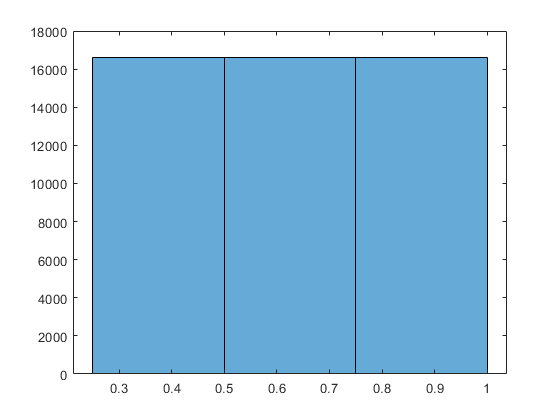

% Fraction of signal block contaminated
edges = 0.25:0.25:1;
histogram(tcontaminated.FracBlockContaminated,edges)

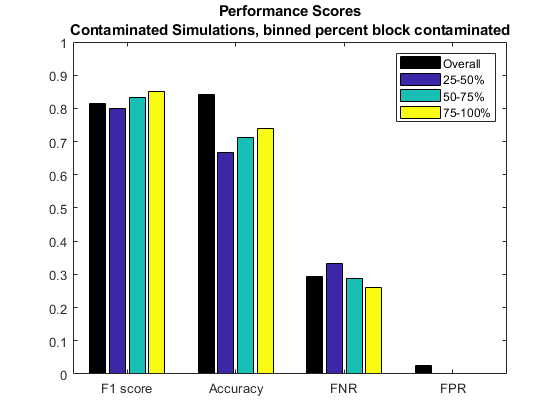

binsfracblock = discretize(tcontaminated.FracBlockContaminated,edges);

[acc,fpr,fnr,f1] = splitapply(@scoreModel,tcontaminated.ContaminatedTrue,tcontaminated.ContaminatedPred,binsfracblock);
% Plot scores for comparison
c = categorical({'F1 score','Accuracy','FNR','FPR'},{'F1 score','Accuracy','FNR','FPR'});
b = bar(c,[[scoresOA.f1 f1']; [scoresOA.acc acc']; [scoresOA.fnr fnr']; [scoresOA.fpr fpr']],'FaceColor','flat');
ylim([0 1])
legend({'Overall','25-50%','50-75%','75-100%'})
title({'Performance Scores';'Contaminated Simulations, binned percent block contaminated'})
b(1).CData = [0 0 0];
for k = 1:length(unique(binsfracblock))
    b(k+1).CData = k;
end

## Analysis of Variance?

Statistical method to estimate how impactiful the changes in SNR and percentage of block contaminated are on the ability of the model to correctly predict the class.

% Create table for analysis
tanova = tmcoutput(:,{'FracBlockContaminated','SNRdB'});
tanova.CorrectPred = tmcoutput.ContaminatedTrue == tmcoutput.ContaminatedPred;

% Check correlation between FracBlockContaminated and SNRdB
% Only valid for contaminated blocks as the non-contaminated blocks have zero for both!
IdxCont = tmcoutput.ContaminatedTrue;
corrcoef(tanova.FracBlockContaminated(IdxCont),tanova.SNRdB(IdxCont))

% Create logistic regression model
mdl11 = fitglm(tanova(IdxCont,:),'linear','distr','binomial')
mdl22 = fitglm(tanova(IdxCont,:),'quadratic','distr','binomial')